**Prediction of the trayectory of the 2023 CubeSat**

1) Calling an API source for meteorological information about the wind direction and gusts on the day and location of the launch.

Meteomatics account info (API):

user     = 'universityofseville_zamorafernandez';   %insert-your-username-here';
password = '9paZ9sDlP2';       %insert-your-password-here';

Location of the Leon Airport:

lat   = 42.590317;
lon   = -5.64593;

Time period we want the prediction to be recieved by the program:

start_date  = floor(now); % Could be anything like a datenum datenum(2016,12,24,12,3,2) <-> '2016-12-24T12:03:02Z';
resolution  = 1/(24*4); % every 15 minutes
end_date    = start_date+2/24; % period of 2 hours from now

Requested parameters are the instantaneous wind speed in m/s, the instantaneous wind direction (in degrees from North), the density at the required altitude:


parameters='wind_speed_20000m:ms,wind_dir_20000m:d,air_density_20000m:kgm3';

Queering the data from the API

[dn,data]=query_time_series_from_weather_api(user,password,start_date,resolution,end_date,parameters,lat,lon);

api.meteomatics.com/2023-04-11T00:00:00Z--2023-04-11T02:00:00Z:PT900S/wind_speed_20000m:ms,wind_dir_20000m:d,air_density_20000m:kgm3/42.59032,-5.64593/csv?matlab_version=MATLAB_(R2021a)&model=mix&calibrated=false


2) Definition of the forces (horizontal, supposing the flight will be constantly at a certain altitude as first approximation) acting on the aerostatic baloon.Propagating Newton's Second Law in order to obtain velocity and position:

rho=data(:,3);
V_wind=data(:,1);
dir=deg2rad(data(:,2));
m=10; %mass of baloon (ask B2Space)
S_wet=200; %ask B2Space
Cd=0.05; %ask B2Space
Delta_t=5;% 5 seconds
for j=1:8 %1 hour prediction
for i=1:180 %180 times 5 seconds until the next prediction (each 15 minutes)
D(i,j)=1/2.*rho(j).*V_wind(j).^2.*S_wet.*Cd;
a(i,j)=D(i,j)/m; %ballon and cubesat moves with the wind
v(i,j)=V_wind(j);
traj(i,j)=V_wind(j)*Delta_t;
end
end


3) Plotting graphs of trayectory, velocity and acceleration (supposing cruise flight and no height variation, for now z=cte)

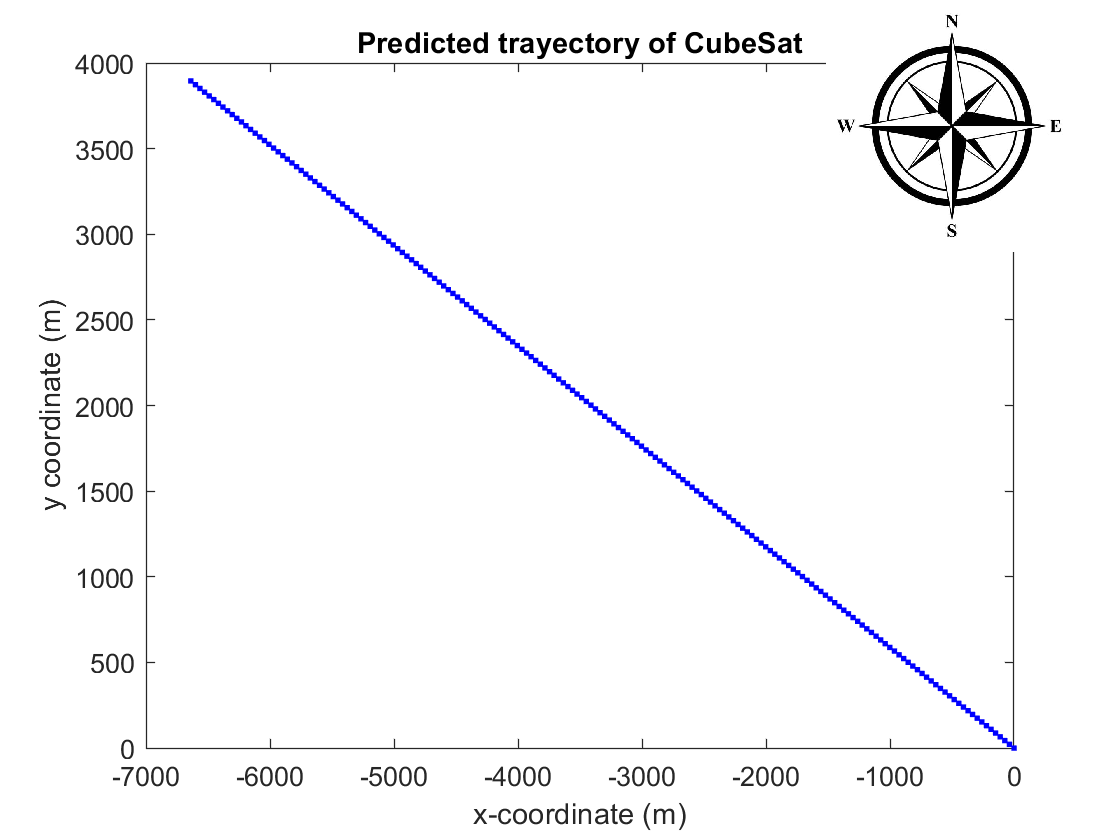

x(1,1)=0; y(1,1)=0;
r=traj(:,1);
theta=dir;

for i=2:180 %only with firt prediction, still remains to update the solution each time a prediction of wind is taken
x(i)=r(i).*sin(theta(1))+x(i-1);
y(i)=r(i).*cos(theta(1))+y(i-1);
if theta(1)>pi/2 && theta(1)<3*pi/2
    y(i)=-y(i);
end

if theta(1)>180
    x(i)=-x(i);
end
end
x_pc=x; %primera columna
y_pc=y;
figure
plot(x,y,'b.')
title('Predicted trayectory of CubeSat')
xlabel('x-coordinate (m)')
ylabel('y coordinate (m)')
axes('pos',[.6 .7 .5 .3]) %[bottomleftcornerXposition bottomleftcornerYposition width height]
imshow('windrose.jpg')

4) Adjusting the prediction every 15 minutes with the wind velocity and direction predictions

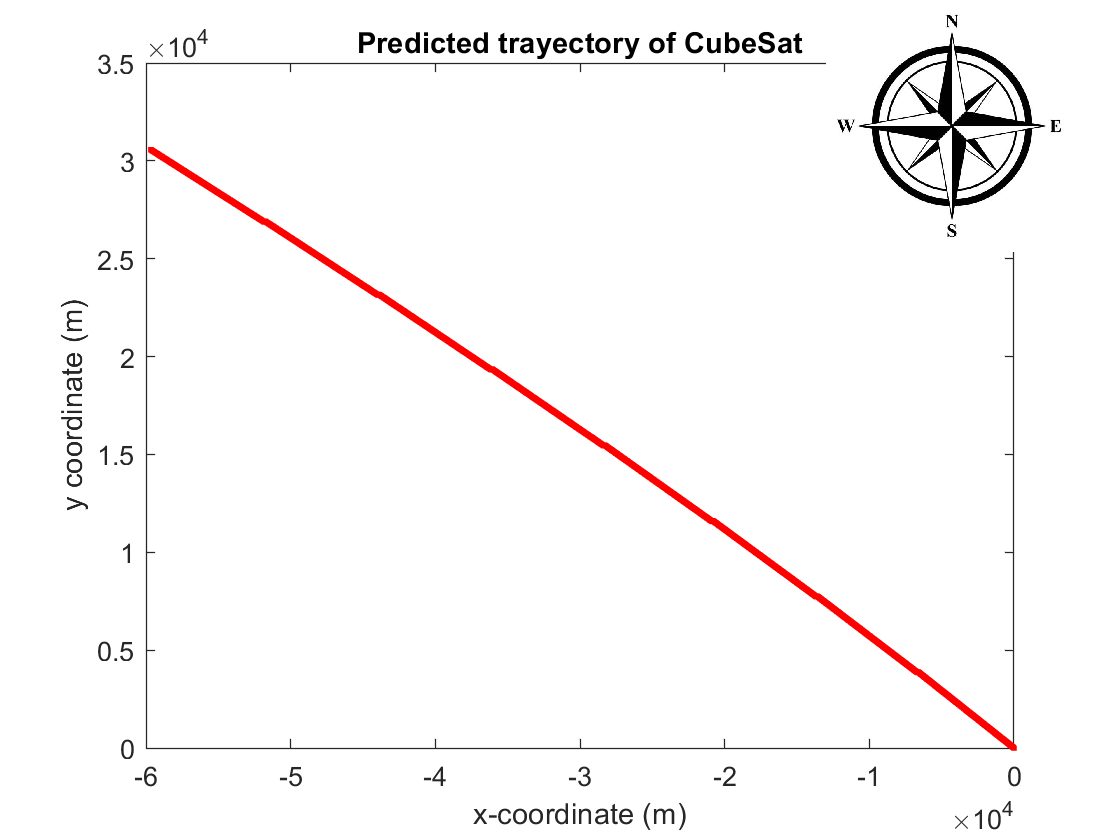

X(:,1)=x_pc; Y(:,1)=y_pc;
r=traj;
theta=dir;
for j=2:8
    X(1,j)=X(180,j-1)+r(1,j).*sin(theta(j));
    Y(1,j)=Y(180,j-1)+r(1,j).*sin(theta(j));
for i=2:180 %only with firt prediction, still remains to update the solution each time a prediction of wind is taken
X(i,j)=r(i,j).*sin(theta(j))+X(i-1,j);
Y(i,j)=r(i,j).*cos(theta(j))+Y(i-1,j);
if theta(j)>pi/2 && theta(j)<3*pi/2
    Y(i,j)=-Y(i,j);
end

if theta(j)>180
    X(i,j)=-X(i,j);
end
end
end

%Tranforming these matrixes to vectors in order to plot correctly
k=1; % vector index
for j=1:8
for i=1:180
    X_plot(k)=X(i,j);
    Y_plot(k)=Y(i,j);
    k=k+1;
end
end
figure

% windrose=imread('windrose.jpg');
% image([-0.5e4, 0] ,[0, 0.5e4], windrose); 
% hold on
plot(X_plot,Y_plot,'r.')
title('Predicted trayectory of CubeSat')
xlabel('x-coordinate (m)')
ylabel('y coordinate (m)')
axes('pos',[.6 .7 .5 .3]) %[bottomleftcornerXposition bottomleftcornerYposition width height]
imshow('windrose.jpg')

5) Plotting velocity and acceleration with time


%Tranforming these matrixes to vectors in order to plot correctly
k=1; % vector index
time=linspace(0,7200,1440) %2 hours in seconds are 7200 seconds but with a time span of 5 seconds

time = 	1.0e+03 *

         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0751    0.0801    0.0851    0.0901    0.0951    0.1001    0.1051    0.1101    0.1151    0.1201    0.1251    0.1301    0.1351    0.1401    0.1451    0.1501    0.1551    0.1601    0.1651    0.1701    0.1751    0.1801    0.1851    0.1901    0.1951    0.2001    0.2051    0.2101    0.2151    0.2202    0.2252    0.2302    0.2352    0.2402    0.2452


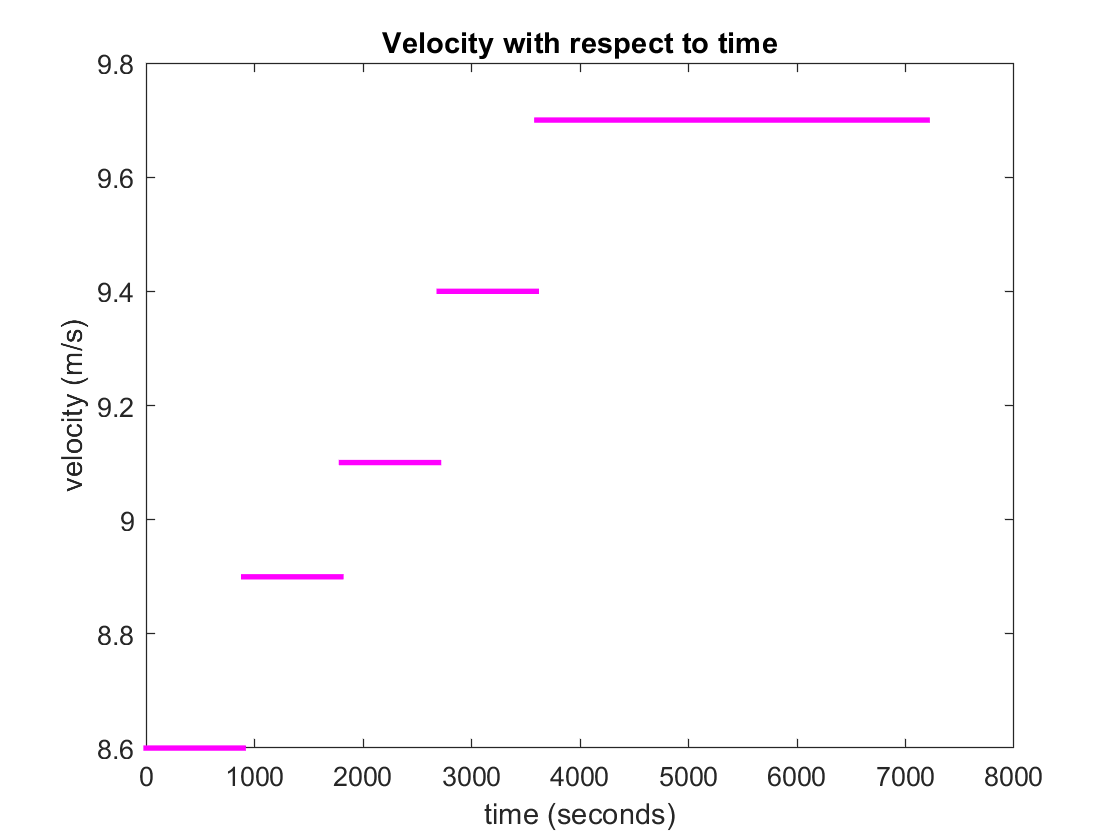

for j=1:8
for i=1:180
    v_plot(k)=v(i,j);
    a_plot(k)=a(i,j);
    k=k+1;
end
end
figure
plot(time, v_plot, 'm.')
title('Velocity with respect to time')
xlabel('time (seconds)')
ylabel('velocity (m/s)')

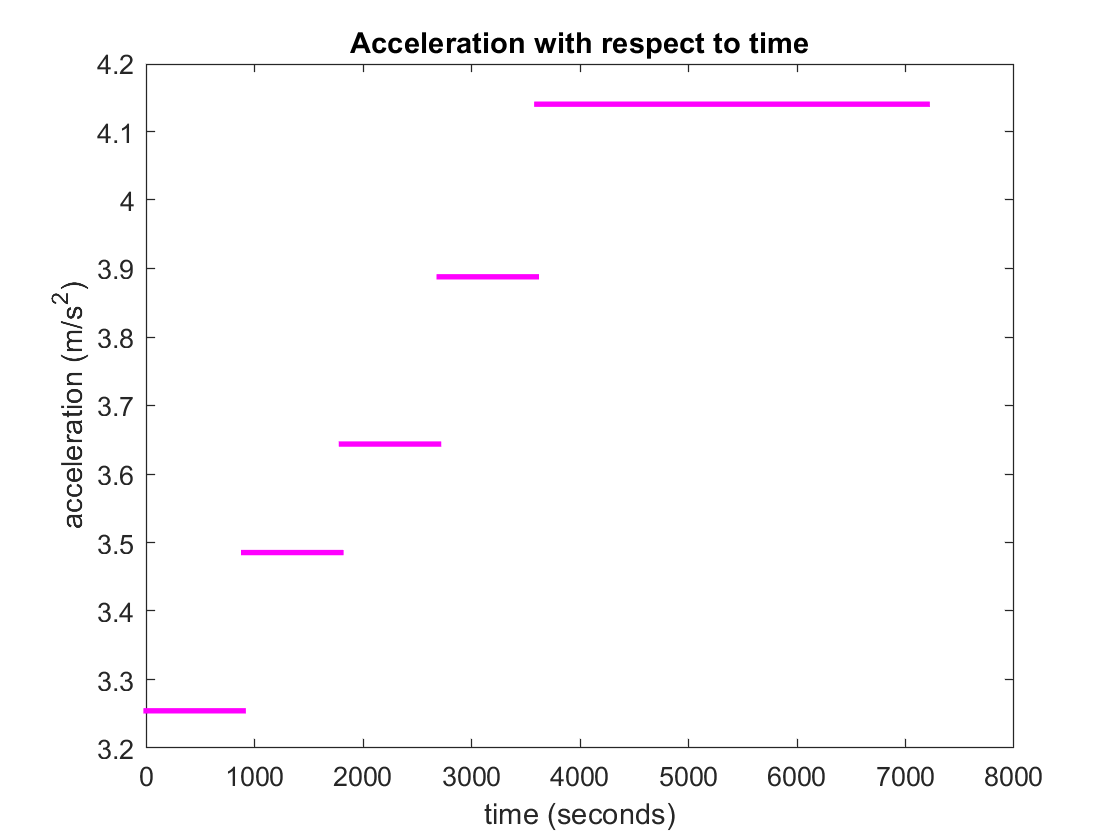

plot(time, a_plot, 'm.')
title('Acceleration with respect to time')
xlabel('time (seconds)')
ylabel('acceleration (m/s^2)')